# Create and Customize Geographic Scatter Plots

`geoscatter` displays color coded markers in a geographic axes at the latitude-longitude locations specified (in degrees) by the vectors `lat` and `lon`.

### Create Latitude and Longitude Data

Define two vectors containing latitude and longitude data respectively for a geoscatter plot.

lon = (-170:10:170);
lat = 50 * cosd(3*lon);

### Basic Plot

Calling geoscratter will plot the latitude longitude pairs on a map of the Earth with default point sizes.

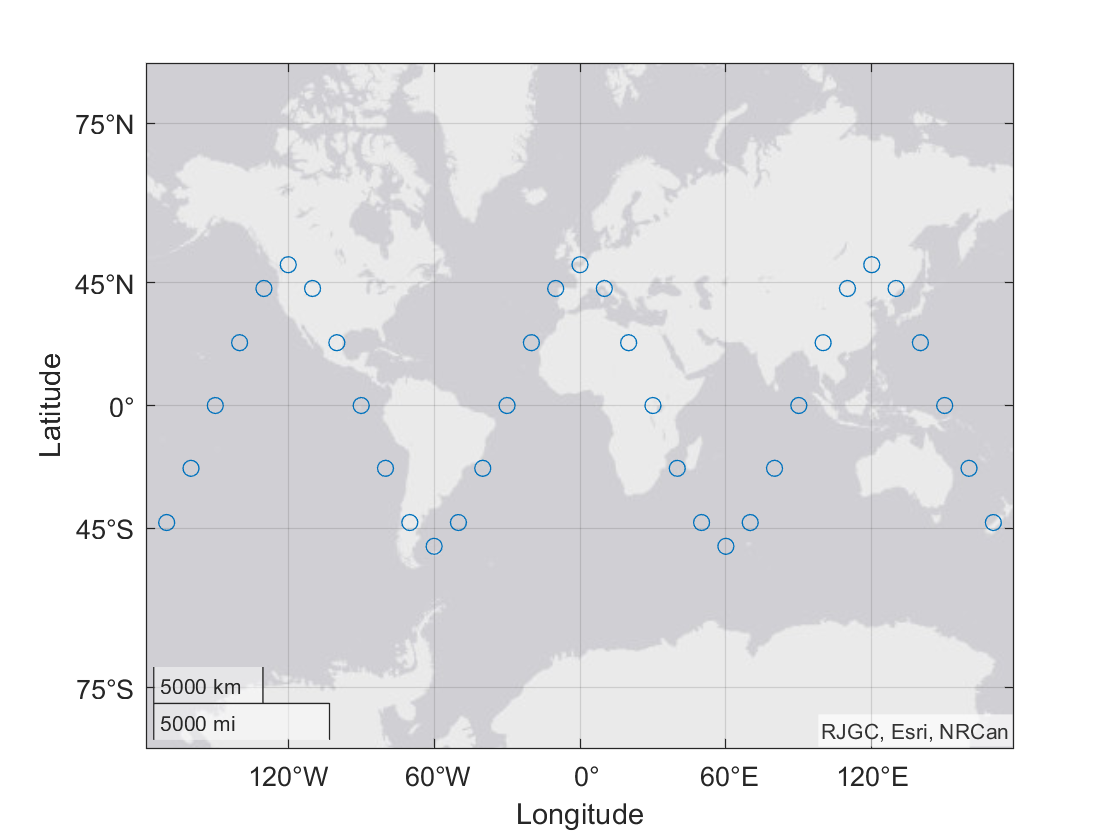

geoscatter(lat,lon);

## Customization

### Specify Point Color

The individual point colors can be specified by passing a matrix of RGB pairs as the *ColorSpec *option which correspond to each latitude-longitude point. The point *EdgeColor* and *FaceColor* properties for the entire data set can be specified using name-value pairs.

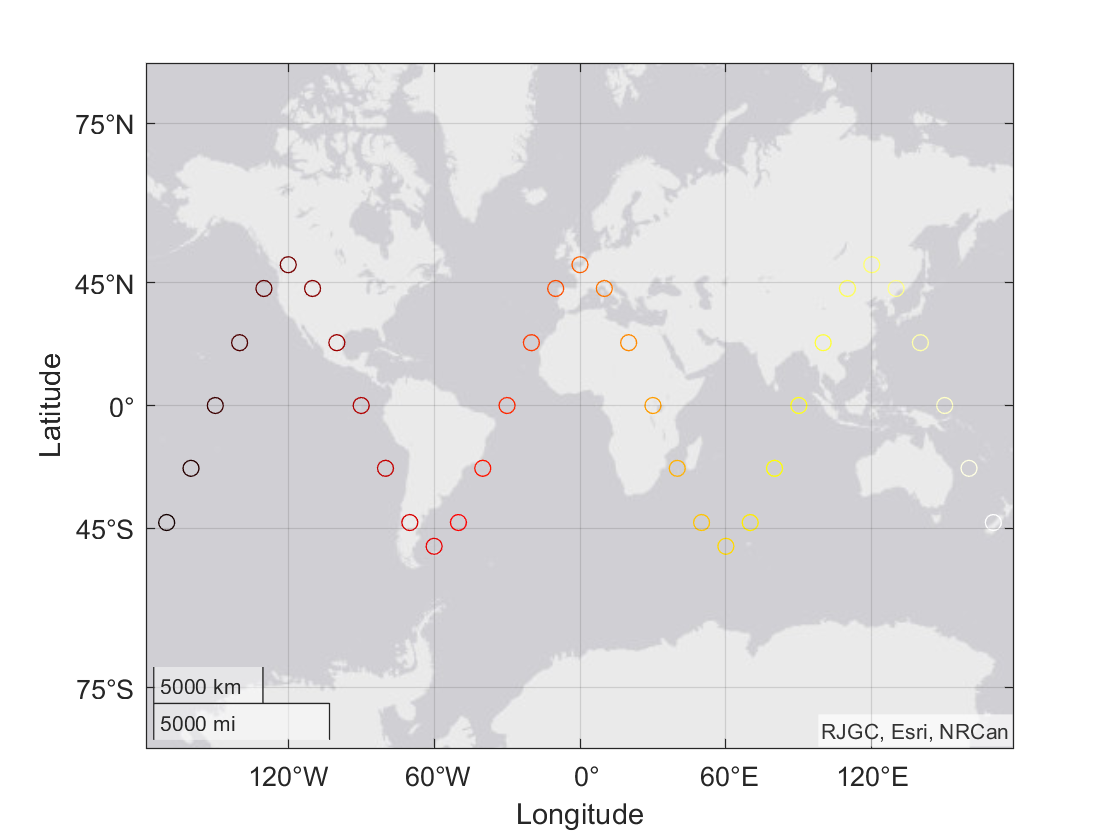

C = hot(length(lat));            % use the hot colormap
geoscatter(lat, lon, [], C)      % Implement the color map as the second input preceding the latitude longitude data            

### Specify Point Shape and Size

The size and shape of individual latitude-longitude points can be customized to improve visiblity or add more information to the plot. A vector containing sizes for every corresponding point can be set as the *SizeData *property. Point symbols can be specified collectively for all the points using the *Marker *property, and can be made more prominent by adjusting the *LineWidth* property.

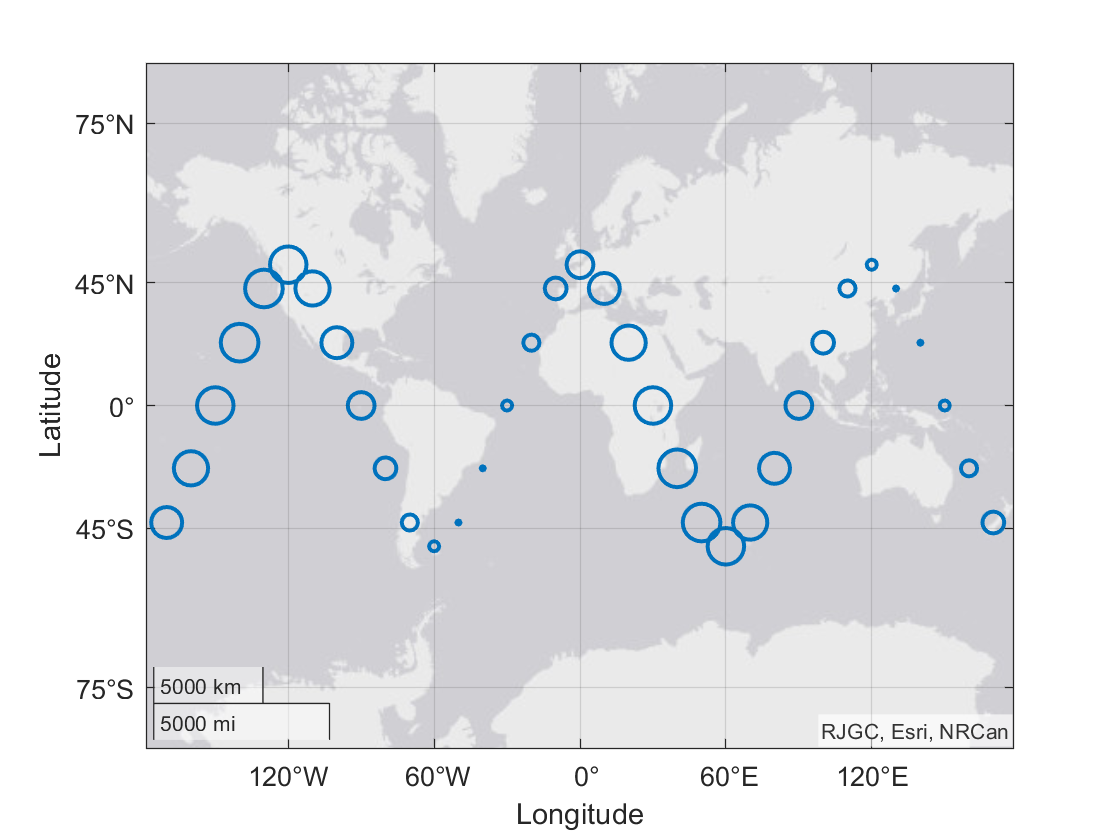

MarkerType = 'o';
LineWidth = 1.5;
A = 101 + 100*(sind(2*lon));
gs = geoscatter(lat, lon,...    
                     "SizeData", A,...              % Specify Size data as a matrix
                     "Marker", MarkerType,...       % Specify point appearance
                     "LineWidth", LineWidth);       % Set the line thickness

### Specify Map Background

Change the appearance of the map by specifying the terrain option in the geobasemap function 

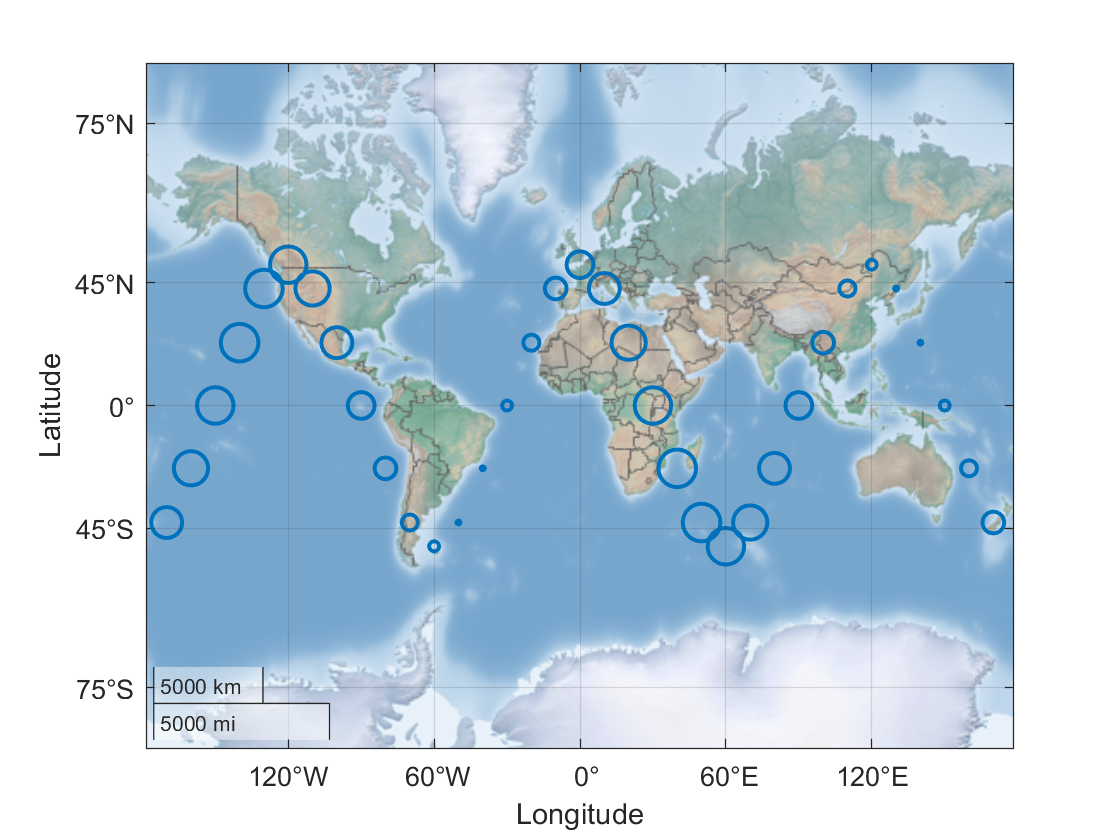

geobasemap colorterrain

## Additional Information

### Get All Geoscatter Properties

Graphics objects in MATLAB have many properties. To see all the properties of a geoscatter, uncomment the following code

% get(gs)

               AlphaData: 1
        AlphaDataMapping: 'scaled'
              Annotation: [1×1 matlab.graphics.eventdata.Annotation]
            BeingDeleted: off
              BusyAction: 'queue'
           ButtonDownFcn: ''
                   CData: [0 0.4470 0.7410]
               CDataMode: 'auto'
             CDataSource: ''
                Children: [0×0 GraphicsPlaceholder]
                Clipping: on
             ContextMenu: [0×0 GraphicsPlaceholder]
               CreateFcn: ''
         DataTipTemplate: [1×1 matlab.graphics.datatip.DataTipTemplate]
               DeleteFcn: ''
             DisplayName: ''
        HandleVisibility: 'on'
                 HitTest: on
           Interruptible: on
            LatitudeData: [1×35 double]
      LatitudeDataSource: ''
          LatitudeJitter: 'none'
     LatitudeJitterWidth: 0.9000
               LineWidth: 1.5000
           LongitudeData: [-170 -160 -150 -140 -130 -120 -110 -100 -90 -80 -70 -60 -50 -40 -30 -20 -10 0 10 20 30 40 50 

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[geoscatter](https://www.mathworks.com/help/matlab/ref/geoscatter.html#d123e476360)